## A simple Fourier transform

*Mark Musil - ****contact@markmusil.com - Aug 4 2022***

####  Step 1 - Load the data

My_data = load('time_series.mat');
time = My_data.t;
signal = My_data.s;
sample_frequency = My_data.fs % Hz

fs = 25

#### 1a. Define some constants

T = 1/sample_frequency

T = 0.0400

size_me_up = size(time);
number_of_samples = size_me_up(2);

#### 2. Plot the time series

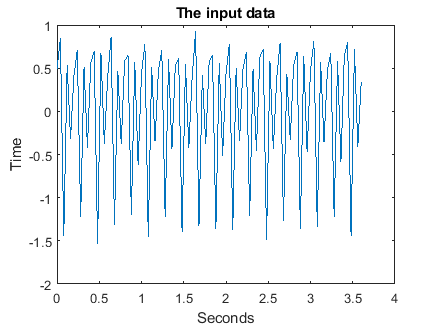

plot(time,signal)
title('The input data')
xlabel('Seconds')
ylabel('Time')

#### 2a. Compute the transform of the signal

Y = fft(signal);

#### 2b. Compute the two-sided spectrum first

two_sided_sprectrum = abs(Y/number_of_samples);

#### 2c. Compute the single-sided spectrum based on the dual-sided spectrum and the even-valued signal length L

single_sided_spectrum = two_sided_sprectrum(1:number_of_samples/2+1);

single_sided_spectrum(2:end-1) = 2*single_sided_spectrum(2:end-1);
single_sided_spectrum(2:end-1) = 2*single_sided_spectrum(2:end-1);

#### Step 3 - Define the frequency domain f

f = sample_frequency*(0:(number_of_samples/2))/number_of_samples;
subplot(2,1,1)
plot(f, single_sided_spectrum)
title('Raw magnitude')
xlabel('Frequency')
ylabel('Magnitude')
max_val = max(single_sided_spectrum);

#### 3a. Plot out the spectrum both in terms of its raw magnitude and in dB relative  to the peak value

subplot(2,1,2)
PdB = 10.*log10(single_sided_spectrum./max_val);
plot(f, PdB)
title('Relative dB to the max peak')
xlabel('Frequency')
ylabel('Relative magnitude')


#### 3b. Use the "text" command to annotate the dB plot to indicate the main and secondary peaks.

text([9.89011, 4.94505], [0, -1.9315], {'Main peak', 'Secondary peak'})

#### 3c .Indicate the level of the secondary peaks (in dB) relative to the main peak.

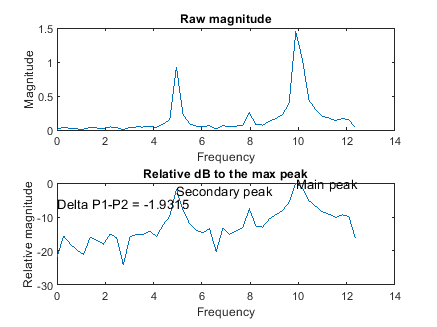

text(0, -6, 'Delta P1-P2 = -1.9315');